# `ImpliedVolatilityChart`** Examples**

**Overview**

The `ImpliedVolatilityChart` creates a smooth, interpolated implied volatility surface for the observed option data $(T, K, \sigma, S)$, where

- $T$ is the expiry time of the option, measured in years;

- $K$ is the strike price of the option, in currency units (e.g., USD or GBP);

- $\sigma$ is the implied volatility, recorded as a decimal value in [0, 1];

- $S$ is the underlying asset price, in currency units.

The chart data comprises a table (`OptionData`) containing four numeric vector variables, namely $T$, $K$, $\sigma$ and $S$ in that order. The observed option data is overlaid on the implied volatility surface for reference. The interpolation method for each volatility curve, or *smile*, is one of `linear`, `spline`, `pchip` (the default), `makima`, `Hagan2002` and `Obloj2008`. The first four methods are non-parametric, and implemented using the `interp1` function. The latter two are variants of the SABR model for computing the implied Black volatility, and are implemented using the `blackvolbysabr` function. In this case the SABR model is calibrated using nonlinear least squares (`lsqnonlin`).

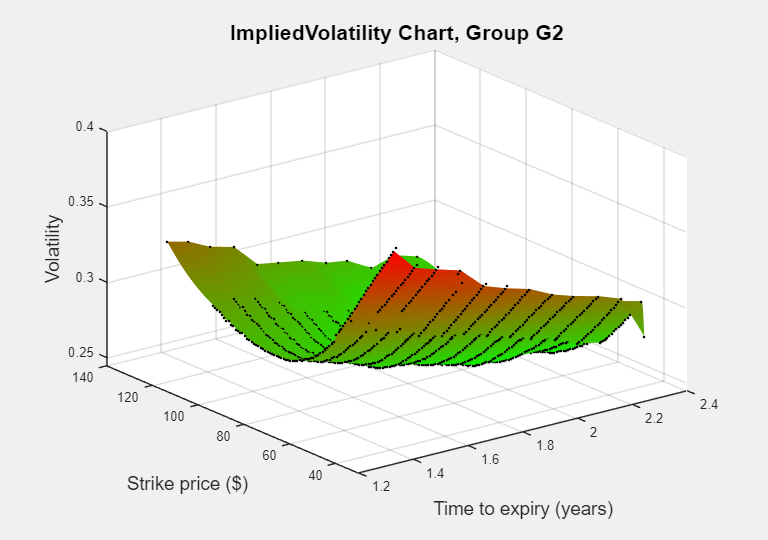

**Resources**

[Open](matlab: edit(fullfile(catalogRoot, "+example", "ImpliedVolatility.mlx"))) this Live Script to run and interact with the examples shown below.

[View](matlab: edit(fullfile(catalogRoot, "+chart", "ImpliedVolatility.m"))) the source code for the `ImpliedVolatilityChart`.

Documentation for:

- [`interp1`](matlab: doc("interp1")): performs 1-D data interpolation

- [`blackvolbysabr`](matlab: doc("blackvolbysabr")): calculates the implied Black volatility using the SABR model

- [`lsqnonlin`](matlab: doc("lsqnonlin")): solves nonlinear least-squares (nonlinear data-fitting) problems

## Load the observed market data.

The market data comprises option expiry times, strike prices and implied volatilities. The times to expiry are divided into different bins, indicated by the variable `Group`. Volatility smiles corresponding to the times in each bin have similar shapes.

load( fullfile( chartsDocRoot(), "data", "Option.mat" ), "D" )

## Create a figure for the chart.

f = exampleFigure( "Name", "ImpliedVolatilityChart Example" );

## Create the chart.

First, extract the option data for a specific group.

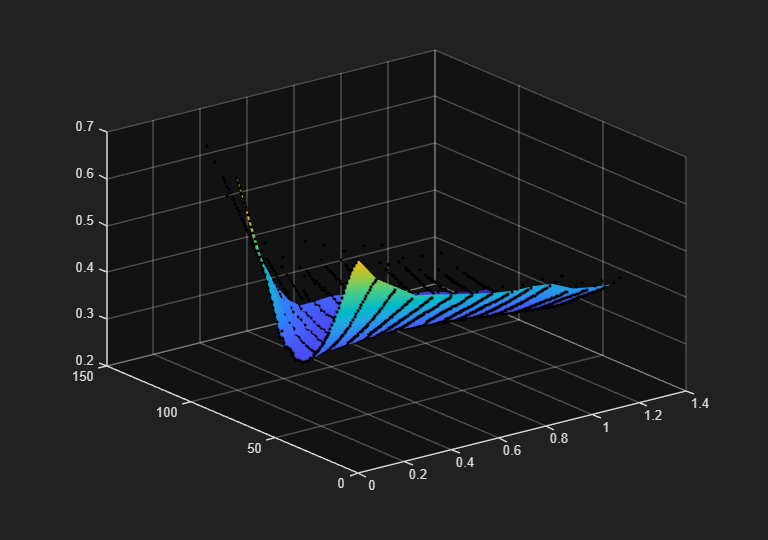

D1 = D(D.Group == "G1", 1:4);
IVC = ImpliedVolatilityChart( "Parent", f, ...
    "OptionData", D1 );

## Annotate the chart.

xlabel( IVC, "Time to expiry (years)", "FontSize", 14 )
ylabel( IVC, "Strike price ($)", "FontSize", 14 )
zlabel( IVC, "Volatility", "FontSize", 14 )
title( IVC, "ImpliedVolatility Chart", "FontSize", 16 )

Add a colorbar.

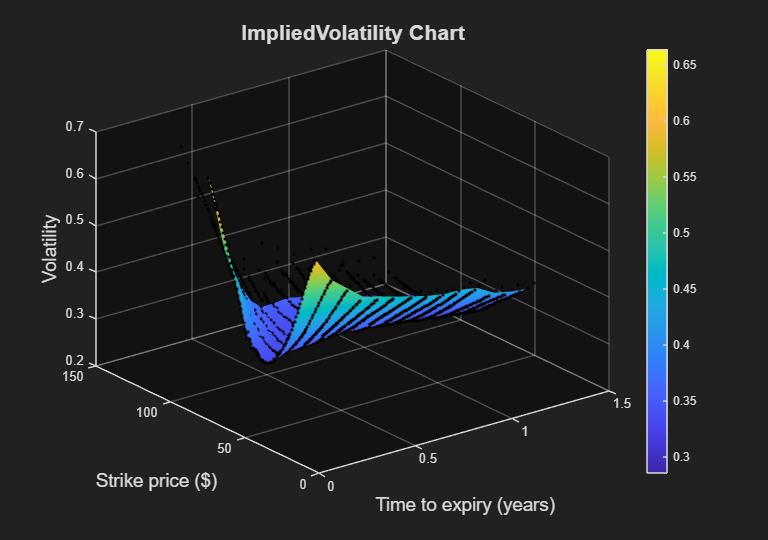

colorbar( IVC )

## Create a custom colormap and apply it to the chart.

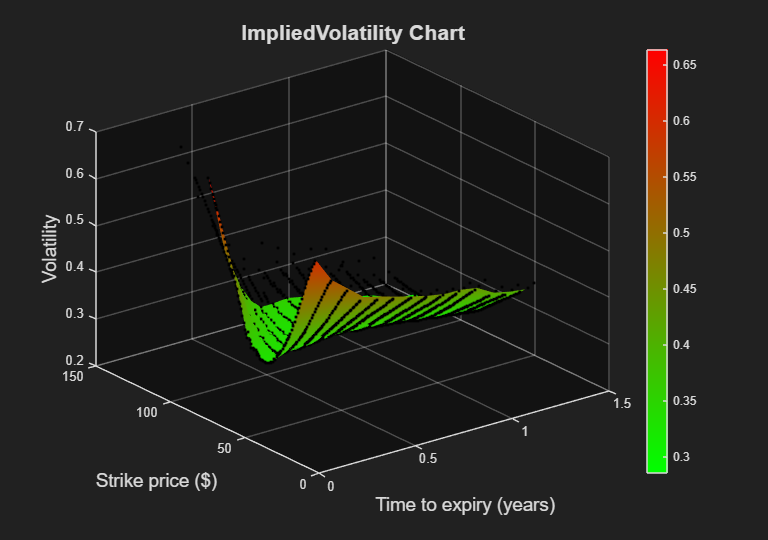

colormap( IVC, money() )

## Restrict the strike prices to lie between $60 and $100.

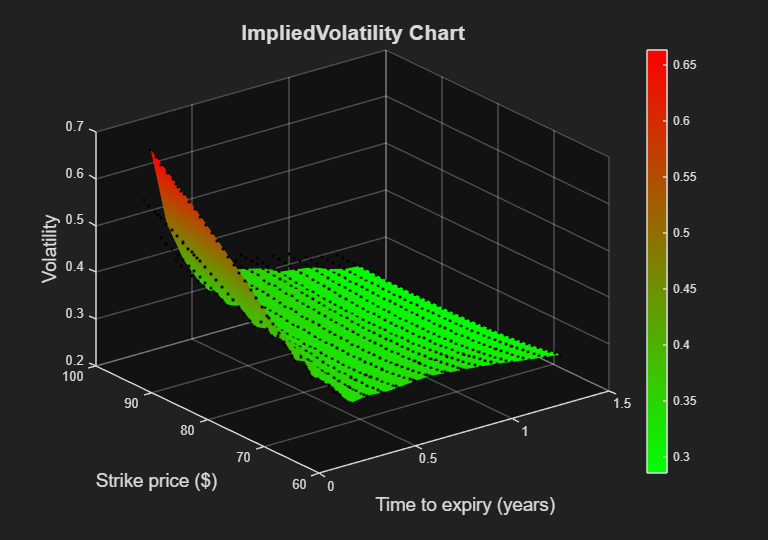

newData = D1(D1.StrikePrice >= 60 & D1.StrikePrice <= 100, :);
IVC.OptionData = newData;

## Remove the first expiry time from the surface.

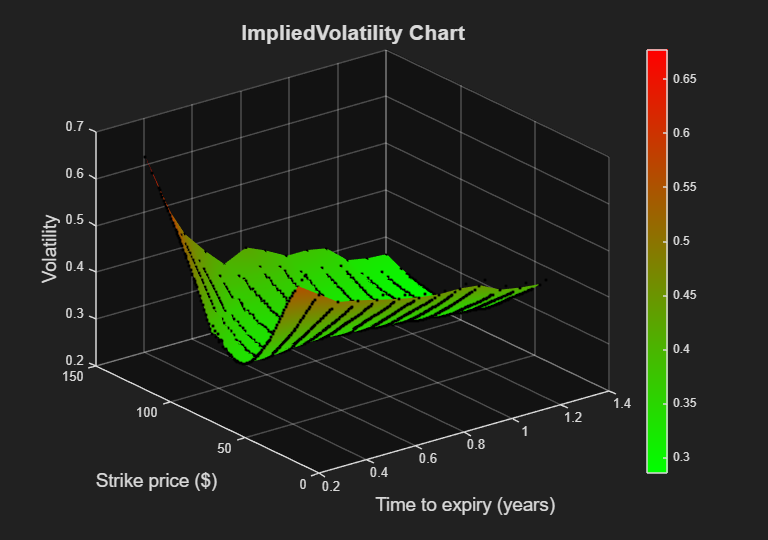

newData = D1(D1.ExpiryTime > D1.ExpiryTime(1), :);
IVC.OptionData = newData;

## Create multiple charts using a grid.

First, create a grid to hold the multiple charts.

f = exampleFigure();
g = uigridlayout( f, [2, 2] );

Loop through the groups, creating a new chart for each group.

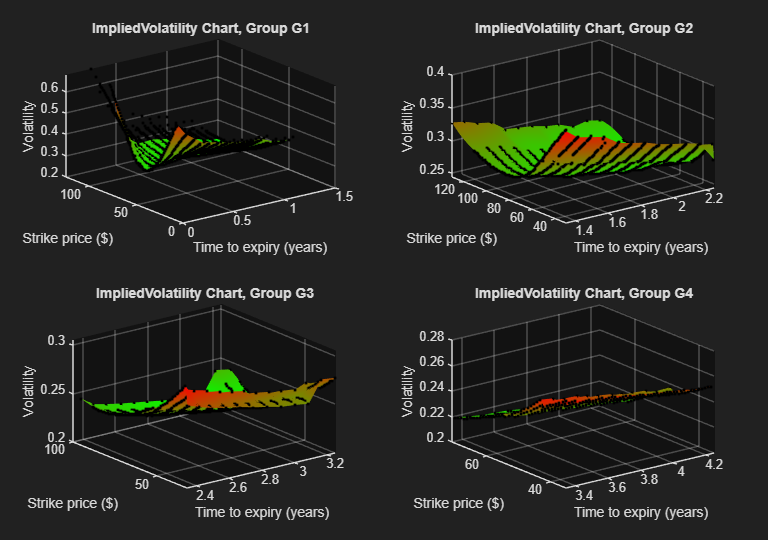

numGroups = 4;
chartsByGroup = cell( 1, numGroups );
for k = 1 : numGroups
    groupIdx = "G" + k;
    chartsByGroup{k} = impVolChart( D, groupIdx, g );
end % for

## Change the surface interpolation method for a specific chart.

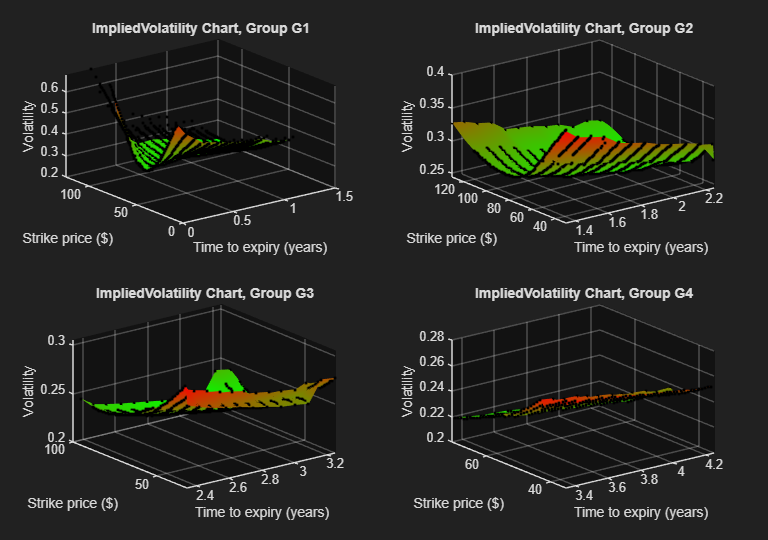

chartsByGroup{2}.InterpolationMethod = "makima";

## Customize the appearance of a specific chart.

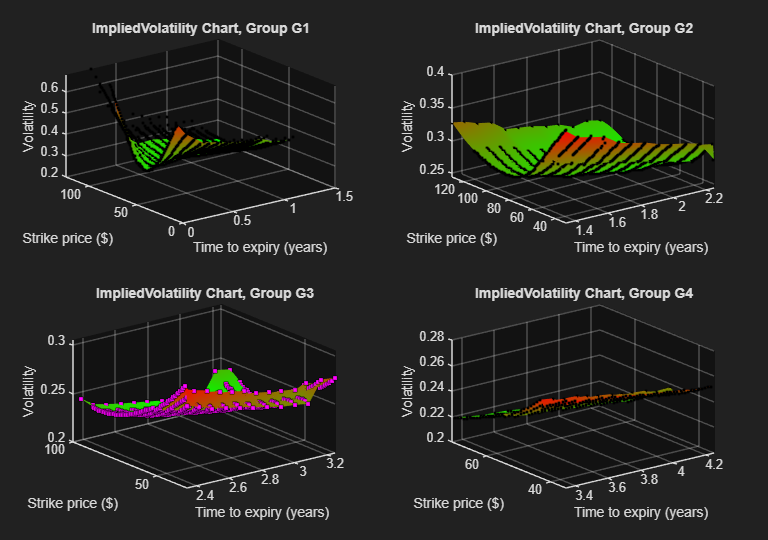

set( chartsByGroup{3}, "Marker", "square", ...
    "MarkerSize", 4, ...
    "MarkerFaceColor", "m", ...
    "MarkerEdgeColor", "k" )

## Local functions.

### Define a custom colormap for use with the implied volatility chart.

function cmap = money()

t = linspace( 0, 1, 256 ).';
cmap = [t, flip( t ), zeros( size( t ) )];

end % money

### Create an implied volatility chart for a given group.

function IVC = impVolChart( D, groupID, parent )

% Extract the option data for the given group.
currentGroupOptionData = D(D.Group == groupID, 1:4);

% Create the chart.
IVC = ImpliedVolatilityChart( "Parent", parent, ...
    "OptionData", currentGroupOptionData );

% Annotate and customize the chart.
xlabel( IVC, "Time to expiry (years)" )
ylabel( IVC, "Strike price ($)" )
zlabel( IVC, "Volatility" )
title( IVC, "ImpliedVolatility Chart, Group " + groupID )
colormap( IVC, money() )

end % impVolChart

*Copyright 2018-2025 The MathWorks, Inc.*